% Age structured model
% Set initial conditions
% Runs model to get optimal effort then saves parameters
% Fikri Sjahruddin

cd ('C:\Users\uqffirma\MATLAB\Projects\FSM\')

%% run and generate initial parameters
fish_list = ["parrot fish" "snapper" "coral trout" "rabbit fish"]; %ordered list species in spparams

num_sp = numel(fish_list);

run sp_parameters.m ;%num_sp is number of all species in spparams

flenm = char('Params_sp');  %set file name to save parameters generated on this code

%% Check length-weight relationship of each species
% Select species which will be plotted

for i = 1: numel(fish_list)
    
    if species == fish_list(i)
        index_sp = i;
    else
    end
end
[spparams] = select_spparams (spparams, index_sp)

spparams = struct with fields:
          nages: 8
              q: 1
              M: 0.5600
         matind: [0 1 1 1 1 1 1 1]
        weights: [201.8409 770.7259 1.5418e+03 2.3288e+03 3.0264e+03 3.5967e+03 4.0406e+03 4.3752e+03]
     weightsmat: [8×3 double]
       fecparam: 1
             CR: 4
           Rmax: 16
       afishind: [8×3 double]
         RelVal: 1
          alpha: 0.0224
           beta: 0.0010
          Lzero: 2.8605e+03
          mrate: 0.0100
          omega: 0
    minbio_prof: 0.0500
        nmonths: 12
             dT: 0.0833


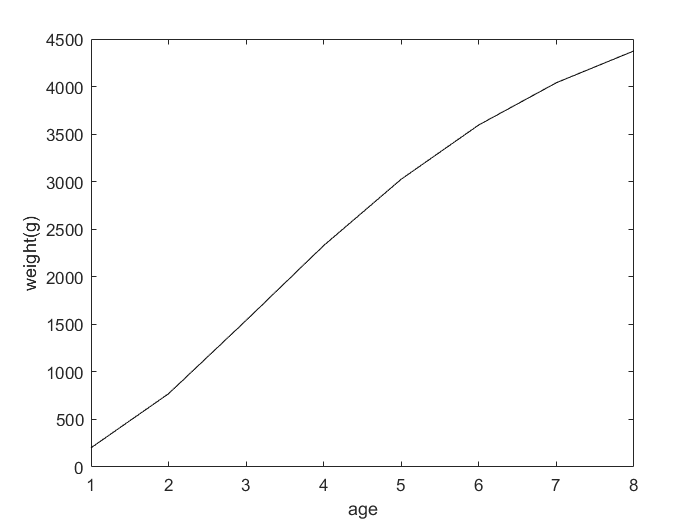

figure
plot(1:spparams.nages, spparams.weights, 'k')
xlabel('age'); ylabel('weight(g)')

%% Initial parameters
Ninit = spparams.Rmax; % intial abundance based on pre-set up maximum recruitment
Ainit = zeros(3,1); %initial area proportion for reserve -2 and fmpa - 3
startmpa = 50;
% Set fishing effort reduction or fishing effort remains within FMPA 
Frem = 0.5; % this means that fishing effort within FMPA remains 50% compared to previous fishing effort before MPA was established
Aval_null = [0 ; 0]; %initial area proportion for reserve -2 and fmpa - 3
tmax = 100; %max - year 100
%% Set fishing mortality assuming fishing does not occur to calculate virgin biomass

umat = arrayfun(@(index_sp) createumat(index_sp, spparams.afishind,0), ...
    index_sp, 'UniformOutput',false);% fishing mortality equals to zero (unfished) - umat for coral trout
xres =  timeloopfunc(Aval_null, umat, index_sp, Ninit,spparams,Ainit, tmax, startmpa,Frem);
b_unfished = xres.Biomass(tmax, 1); %unfished biomass when fishing does not occur

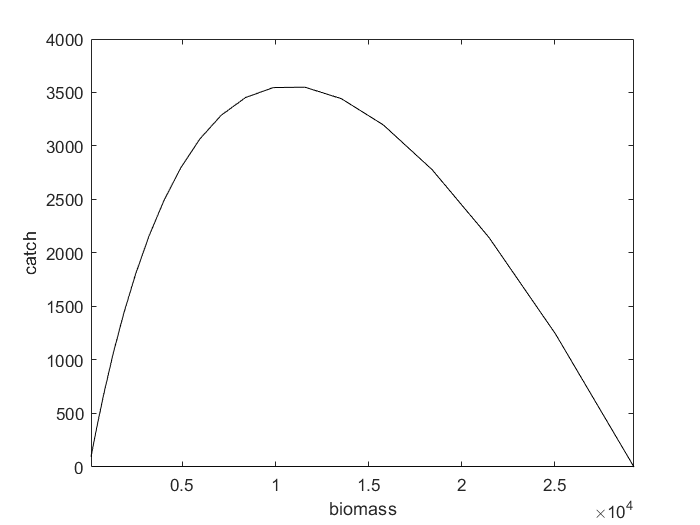

%% Find Fmsy, no MPA implemented, check optimum fishing effort to generate max catch
sppvals = [1]; %column -th , 
nvals = 20; %setting number to generate fishing effort
uvals = linspace(0,0.8,nvals); %fishing efforts
catchvals = nan(nvals,1); %catch resulted based on fishing efforts applied
biovals = nan(nvals,1); %biomass resulted based on fishing efforts applied

for ivals = 1:nvals   %number of diffrerent fishing efforts
umat = arrayfun(@(index_sp) createumat(index_sp, spparams.afishind, uvals(ivals)),index_sp, 'UniformOutput',false);
xres =  timeloopfunc(Aval_null, umat, index_sp, Ninit,spparams,Ainit, tmax, startmpa,Frem);
 %only for one species
 catchvals(ivals)= xres.Catches(tmax,sppvals);
 biovals(ivals) = xres.Biomass(tmax,sppvals);
end

figure
	plot(biovals, catchvals, 'k'); xlabel ('biomass'); ylabel ('catch')
    xlim([min(biovals) max(biovals)])
    %ylim([round(min(catchvals)) ceil(max(catchvals))])
	yline(0,'k')

%% Find optimum effort to generate max catch using fminsearch and fmincon
%%%% Run models to find Fmsy
%%% Find optimal effort 


nvals = 1; %nvals = 1 because optimisation is being focused on values on each simulations
fun = @(x) -getvalsMP_sp(nvals,Aval_null,x, index_sp,spparams,Ainit, Ninit, tmax, startmpa); %functions used in the optimisation. It is used because it generates output total catch for each species all over the zones 
x0 = 0; %simulation starts 
options = optimset('Display','iter');
[Eopt Copt] = fminsearch(fun,x0, options)

 
 Iteration   Func-count     min f(x)         Procedure
     0            1               -0         
     1            2         -8.54135         initial simplex
     2            4         -25.5791         expand
     3            6         -59.4752         expand
     4            8         -126.555         expand
     5           10           -257.9         expand
     6           12         -509.621         expand
     7           14         -971.384         expand
     8           16          -1744.3         expand
     9           18         -2796.39         expand
    10           20         -3553.02         expand
    11           22         -3553.02         contract outside
    12           24         -3553.27         contract inside
    13           26         -3560.39         contract inside
    14           28         -3560.39         contract inside
    15           30         -3560.39         contract outside
    16           32         -3560.39         contract inside


Eopt = 0.2717

Copt = -3.5604e+03

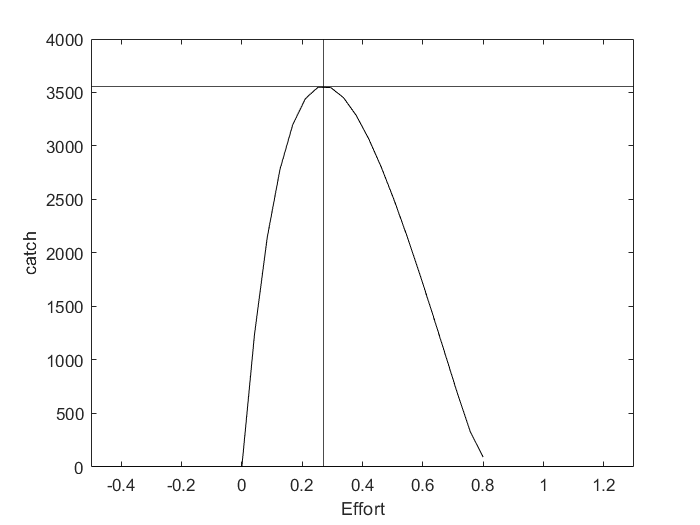

figure
	plot(uvals, catchvals, 'k'); xlabel ('Effort'); ylabel ('catch');
    xlim([min(uvals)-0.5 max(uvals)+0.5]);
	xline(Eopt,'k');
    yline(-Copt,'k');
	yline(0,'k');

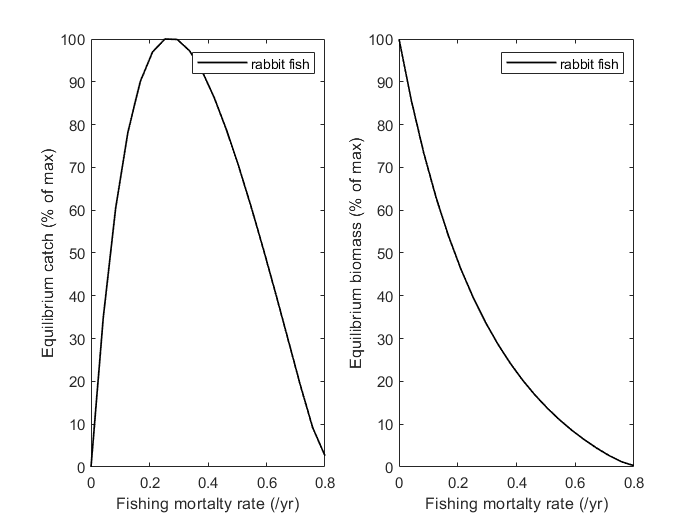


%% Effort plot for paper
figure

lstyle = {'-' };
lcolor = [0 0 0];

maxcatch = max(catchvals);
subplot(1,2,1);
plot(uvals,100*catchvals/maxcatch, lstyle{1,1}, 'Color', lcolor,'LineWidth',1, 'MarkerFaceColor','k', 'MarkerSize',4, 'DisplayName',fish_list(index_sp));
xlabel('Fishing mortalty rate (/yr)'); ylabel('Equilibrium catch (% of max)');
legend(fish_list(index_sp));    

subplot(1,2,2)
maxbio = max(biovals);
plot(uvals,100*biovals/maxbio, lstyle{1,1}, 'Color', lcolor,'LineWidth',1, 'MarkerFaceColor','k', 'MarkerSize',4, 'DisplayName',fish_list(index_sp));
xlabel('Fishing mortalty rate (/yr)'); ylabel('Equilibrium biomass (% of max)');
legend(fish_list(index_sp));

%% Plot N1, Biomass, and Catch over time for two scenarios
% Scenario 0, FP = 1 = Fmsy, no MPA, no reserve
% Scenario 1, FP = 1 = Fmsy, reserve = 30%, FMPA = 20%

%Fishing pressure st up
FPmult = [1 1.5 2.0];
Btot = Eopt * FPmult(3); %Fishery condition is set as overfished
umat = arrayfun(@(index_sp) createumat(index_sp, spparams.afishind,Btot), ...
    index_sp, 'UniformOutput',false); %This makes u or fishing efforts are the same for all species

%run scenario over time
xres_0 = timeloopfunc([0; 0], umat, index_sp, Ninit,spparams, Ainit, tmax, startmpa,Frem); %Scenario 0
 
xres_1 = timeloopfunc([0.15; 0.15], umat, index_sp, Ninit, spparams, Ainit, tmax, startmpa,Frem); %Scenario 1
 
Scenarios = {xres_0 xres_1};

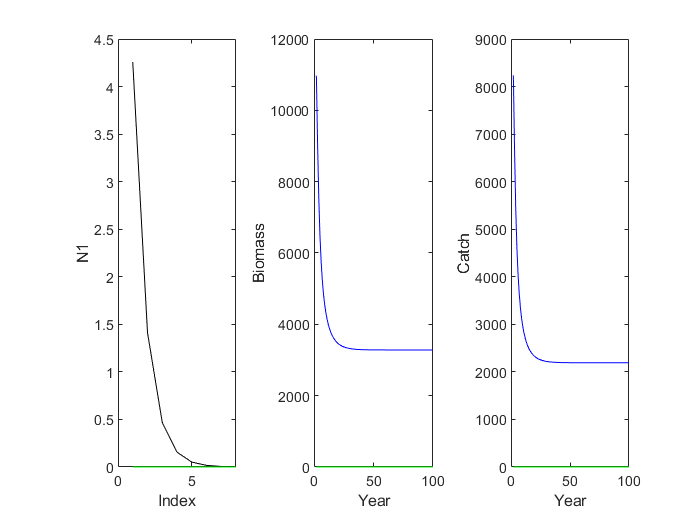

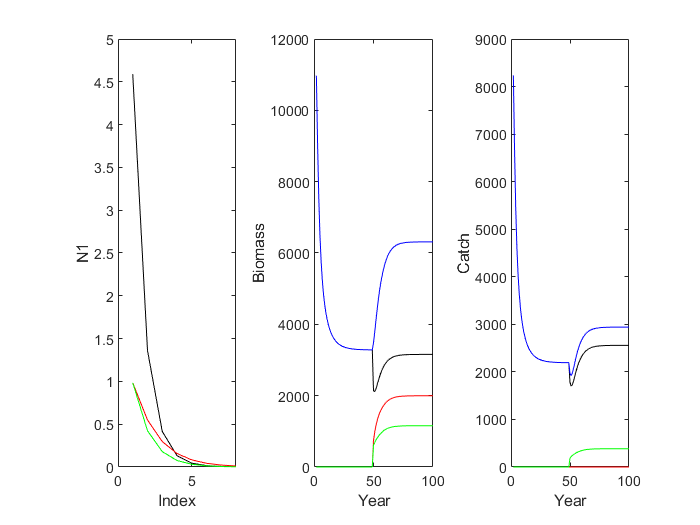


for p = 1:numel(Scenarios)

figure

xres = Scenarios{1,p};

    subplot(1,3,1)
	plot(xres.N1{1,1}(:,1), 'k');
    hold on
	plot(xres.N1{1,1}(:,2), 'r'); 
    plot(xres.N1{1,1}(:,3), 'g'); xlabel ('Index'); ylabel ('N1')
   
	subplot(1,3,2)
    
	plot(1:tmax, xres.Biomass(:,1), 'k')
    ylim = [0 max(sum(xres.Biomass(:,1:3),2))];
    hold on
	plot(1:tmax, xres.Biomass(:,2),'r');
    plot(1:tmax, xres.Biomass(:,3),'g');
    plot(1:tmax, sum(xres.Biomass(:,1:3),2), 'b'); 
    xlabel ('Year'); ylabel ('Biomass');
	  
    subplot(1,3,3)
    
	plot(1:tmax, xres.Catches(:,1), 'k')
    ylim = [0 max(sum(xres.Catches(:,1:3),2))];
    hold on
	plot(1:tmax, xres.Catches(:,2),'r');
    plot(1:tmax, xres.Catches(:,3),'g');
    plot(1:tmax, sum(xres.Catches(:,1:3),2), 'b'); 
    xlabel ('Year'); ylabel ('Catch');
end

%% Save parameters

output =struct();
output.spparams = spparams;
output.Copt = Copt;
output.Eopt = Eopt;
output.FPmult = FPmult;
output.nmonths = spparams.nmonths;
output.dT = spparams.dT;
output.Ninit = Ninit;

save( flenm, 'output') %save all object as output object    